# Esame CALCOLO NUMERICO 24/06/2024

## Esercizi

### 1

Sia $x_1 =1\ldotp 57079$ e $x_2 =1\ldotp 57078$

- Individuare la variazione dei dati, calcolandone l'errore relativo

- Calcolare $\cos \left(x_1 \right)$ e $\cos \left(x_2 \right)$ e valutare la variazione relativa della soluzione

- Fornire la definizione di condizionamento e commentare i risultati ottenuti

% Variazione dei dati con errore relativo
% e = (abs(v_exact - v_approx) / abs(v_exact));
x1 = 1.57079; x2 = 1.57078;

e = (abs(x1 - x2) / abs(x1))

e = 6.3662e-06


% Variazione dei risulati con errore relativo
y1 = cos(x1); y2 = cos(x2);

e = (abs(y1 - y2) / abs(y1))

e = 1.5806

Chiamiamo condizionamento di una funzione o metodo, quel numero che al variare di $k$ fa valere la seguente


$$\frac{||f\left(x+\delta x\right)-f\left(x\right)||}{||f\left(x\right)||}\le k\cdot \frac{||\delta x||}{||x||}$$


Con $k$ "piccolo" diciamo che il sistema è ben condizionato, altrimenti diciamo che è "mal condizionato". Notiamo come l'errore relativo sui dati (`6.366223365213344e-06`) sia significativamente inferiore rispetto all'errore sui risultati (`1.580579134061397`): l'ipotetico sistema è mal condizionato.

### 2

Data la matrice$A=\left\lbrack \begin{array}{ccc}
1 & 0 & -1\\
0 & 4 & 1\\
-1 & 1 & 5
\end{array}\right\rbrack$

- Costruire sul foglio la fattorizzazione ${\textrm{LL}}^T$ con l'algoritmo riga-colonna in modo tale che $A={\mathrm{LL}}^T =\left\lbrack \begin{array}{ccc}
l_{11}  & 0 & 0\\
l_{21}  & l_{22}  & 0\\
l_{31}  & l_{32}  & l_{33} 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
l_{11}  & l_{21}  & l_{31} \\
0 & l_{22}  & l_{32} \\
0 & 0 & l_{33} 
\end{array}\right\rbrack$

- Verificare in MATLAB che la fattorizzazione sia corretta attraverso l'uso del comando `norm`.

La fattorizzazione ${\textrm{LL}}^T$ di Cholesky, anche detta riga-colonna, produce una matrice triangolare inferiore che quando moltiplicata alla sua trasposta, produce la matrice originale $A$. La matrice originale deve essere simmetrica o Hermitiana perché l'algoritmo funzioni. Una formula per componenti esiste, su carta è più facile risolvere il sistema lineare riga-colonna quando la matrice è di piccole dimensioni: prendiamo la prima riga di $L$ e la moltiplichiamo per le colonne di $L^T$ e così facciamo per il resto.

- 
$$\mathrm{R1}\left(L\right)*\mathrm{C1}\left(L^T \right)=1\to l_{11}^2 =1\to l_{11} \in \left\lbrace -1,1\right\rbrace$$


- 
$$\mathrm{R1}\left(L\right)*\mathrm{C2}\left(L^T \right)=0\to l_{11} l_{21} =0\to l_{21} =0$$


- 
$$\mathrm{R1}\left(L\right)*\mathrm{C3}\left(L^T \right)=-1\to l_{11} l_{31} =-1\to l_{31} =-l_{11}$$


- 
$$\mathrm{R2}\left(L\right)*\mathrm{C1}\left(L^T \right)=0\to l_{21} l_{11} =0$$


- 
$$\mathrm{R2}\left(L\right)*\mathrm{C2}\left(L^T \right)=4\to l_{22}^2 =4\to l_{22} \in \left\lbrace -2,2\right\rbrace$$


- 
$$\mathrm{R2}\left(L\right)*\mathrm{C3}\left(L^T \right)=1\to l_{22} l_{32} =1\to l_{32} =\frac{1}{l_{22} }$$


- 
$$\mathrm{R3}\left(L\right)*\mathrm{C1}\left(L^T \right)=-1\to l_{31} l_{11}$$


- 
$$\mathrm{R3}\left(L\right)*\mathrm{C2}\left(L^T \right)=1\to l_{32} l_{22}$$


- 
$$\mathrm{R3}\left(L\right)*\mathrm{C3}\left(L^T \right)=5\to l_{33}^2 =5\to l_{33}^2 =-1-\frac{1}{4}+5\to l_{33} \in \left\lbrace -\frac{\sqrt{15}}{2},\frac{\sqrt{15}}{2}\right\rbrace$$



$$L=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 2 & 0\\
-1 & \frac{1}{2} & \frac{\sqrt{15}}{2}
\end{array}\right\rbrack$$


A = [1 0 -1; 0 4 1; -1 1 5]

A =      1     0    -1
     0     4     1
    -1     1     5


L = [1 0 0; 0 2 0; -1 1/2 sqrt(15)/2] % chol(A)'

L =     1.0000         0         0
         0    2.0000         0
   -1.0000    0.5000    1.9365


L * L'

ans =      1     0    -1
     0     4     1
    -1     1     5


norm(abs(A-(L*L')), "inf") % Norma infinito deve essere 0

ans = 0

### 3

Dato l'integrale $\int_{-1}^1 \sqrt{1-x^2 }\mathrm{dx}$

- Fare il grafico della funzione integranda nel dominio di integrazione.

- Programmare in MATLAB una function con la formula dei trapezi composita costruita su una decomposizione di $N$ sottointervalli del dominio di integrazione.

- Costruire una tabella con l'andamento dell'errore all'aumentare del numero di sottointervalli $N$ della decomposizione.

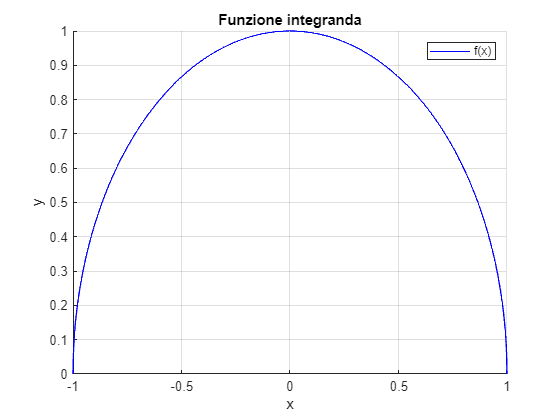

%% Grafico della funzione
f = @(x) sqrt(1-x.^2);
x = linspace(-1, 1, 1000);

figure; hold on; grid on
xlabel('x'); ylabel('y')
title('Funzione integranda')
plot(x, f(x), 'b-', 'DisplayName', 'f(x)')
legend


%% Trapezio composita su f
a = -1; b = 1;

q0 = integral(f, a, b); % Valore esatto

m = 10:100:1000; % Numero intervalli
q = zeros(1,length(m)); % Vettore integrali approssimati
e = zeros(1,length(m)); % Vettore errori

for i = 1:length(m)
    q(i) = trapezio_composita(f, a, b, m(i));
    e(i) = abs(q0 - q(i));
end

q0   % Valore esatto

q0 = 1.5708

q(i) % Valore approssimato

ans = 1.5707

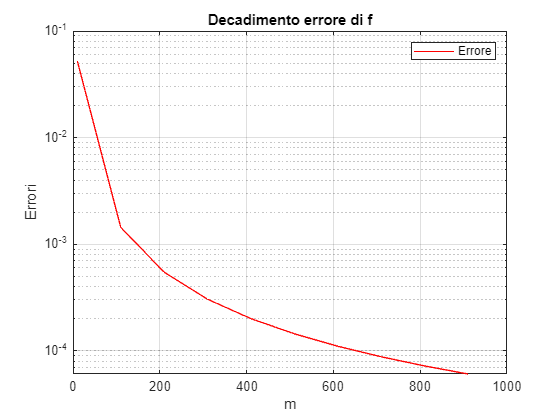


%% Grafico del decadimento dell'errore
figure;
semilogy(m, e, 'r-', 'DisplayName', 'Errore')
hold on; grid on
xlabel('m'); ylabel('Errori')
title('Decadimento errore di f')
legend


%% Tabella del decadimento dell'errore
table(m', e', 'VariableNames', {'Numero Intervalli', 'Errore'})

ans = 10×2 table
    Numero Intervalli      Errore  
    _________________    __________

            10             0.052272
           110            0.0014407
           210           0.00054634
           310           0.00030464
           410            0.0002003
           510           0.00014438
           610           0.00011038
           710             8.79e-05
           810           7.2137e-05
           910           6.0579e-05
